# cwEDMR on Pin SC using chip

Spectra obtained by Michele using the EDMRoC.

clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

% File and Run options
Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New Chip';
Opt.Ldir = dir([Opt.LFolder, '\*Constant.txt']);

Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';

% 1.2V, 1.1V, 1.3V, 1.4V, 1.5V, 1.6V
Idc = [177 000 225 280 341 382]; % uA
cw = struct();
ncw = numel(Opt.Ldir);
for icw = 1:ncw
    LPath_ = [Opt.LFolder, '\', Opt.Ldir(icw).name];
    cw(icw).data = importdata(LPath_, '\t');
    
    cw(icw).x = cw(icw).data(:, 1)/10;
    % Multiply times 10 to make the units a bit more readeable
    cw(icw).ch1 = cw(icw).data(:, 2)*10;
    cw(icw).ch2 = cw(icw).data(:, 3);
    cw(icw).ch3 = cw(icw).data(:, 4);
    cw(icw).ch4 = cw(icw).data(:, 5);

    newStr = strsplit(Opt.Ldir(icw).name, '_');
    cw(icw).Title = [strrep(newStr{3}, 'p', '.'), ' ', num2str(Idc(icw)), 'uA'];
end
% Reordering
cw(7) = cw(1); cw(1) = cw(2); cw(2) = cw(7);
cw(7) = [];

% Measurement cw(2) does not show any signal
% Overwrite it with the measurement 003
LPath_ = [Opt.LFolder, '\', '003_aSi_1p2V_labview.txt'];
cw(2).data = importdata(LPath_, '\t');

cw(2).x = cw(2).data(:, 1)/10;
cw(2).ch1 = cw(2).data(:, 2)*10;
cw(2).ch2 = cw(2).data(:, 3);
cw(2).ch3 = cw(2).data(:, 4);
cw(2).ch4 = cw(2).data(:, 5);

#### Baseline correction

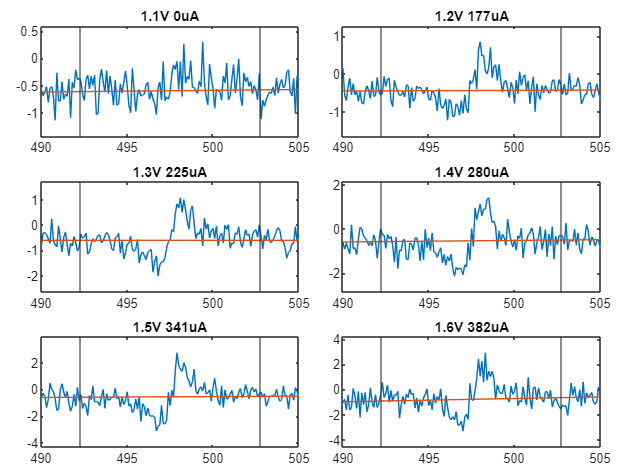

Opt.Bl.Order = 1;
Opt.Bl.Width = 0.15;

for icw = 1:ncw
    cw(icw).BlOpt = Opt.Bl;
    % y1 is the spectrum baseline corrected but not phase corrected
    [cw(icw).y1, cw(icw).Bl] = ...
        subtractBaseline(cw(icw).x, cw(icw).ch1, Opt.Bl);
end

nFig = 1;
for iFig = 1:nFig
    figure();
    tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact')
    for icw = (iFig-1)*ncw/nFig + 1:iFig*ncw/nFig
        nexttile()
        x_ = cw(icw).x; ch1_ = cw(icw).ch1; Bl_ = cw(icw).Bl;
        Width_ = cw(icw).BlOpt.Width;
        plot(x_, ch1_, x_, Bl_);
        xlim(setAxLim(x_, 0)); ylim(setAxLim(ch1_, 0.2));
        xline(min(x_) + Width_*(max(x_) - min(x_)));
        xline(max(x_) - Width_*(max(x_) - min(x_)));
        title(cw(icw).Title)
    end
end

#### Phase correction

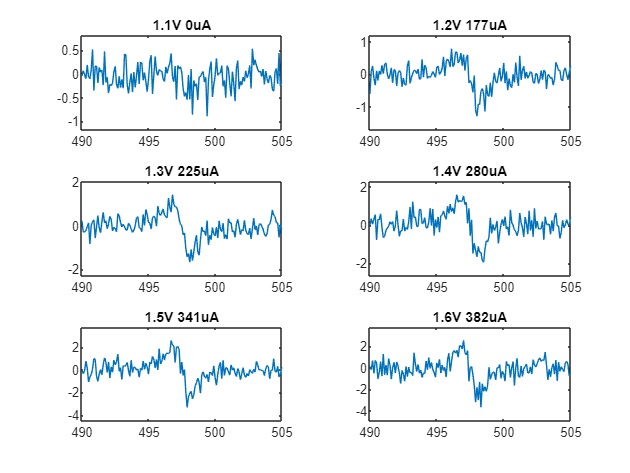

% y2 is the spectrum baseline and phase corrected
for icw = 1:ncw
    % y is the spectrum baseline and phase corrected
    cw(icw).Phase = 180;
    cw(icw).y = -cw(icw).y1;
end

figure();
tiledlayout('flow');
for icw = 1:ncw;  nexttile; 
    plot(cw(icw).x, real(cw(icw).y));
    xlim(setAxLim(cw(icw).x, 0)); ylim(setAxLim(real(cw(icw).y), 0.2));
    title(cw(icw).Title)
end

#### Manual

% mpcModel = @(y2, p) y2 * exp(1i*p*pi/180);
% mpcArray = zeros(numel(cw(1).x), 181); % Array of phase corrected data
% mpc = {mpcArray, mpcArray, mpcArray, mpcArray};
% for impc = 1:ncw
%     mpcArray_ = mpcArray;
%     for iP = -90:90
%         mpcArray_(:,90 + iP + 1) = mpcModel(cw(impc).y2, iP*1);
%     end
%     mpc{impc} = mpcArray_;
% 
%     figure()
%     % Phase at which the scrollable starts. Set p0 = 0 if the phase
%     % correction was already done
%     p0 = 0;
%     h1 = ScrollableAxes('Index', 91 + 1 + p0); 
%     plot(h1, cw(impc).x, -90:90, real(mpc{1, impc}));
%     hold on
%     plot(h1, cw(impc).x, -90:90, imag(mpc{1, impc}));
% end

#### Final plot

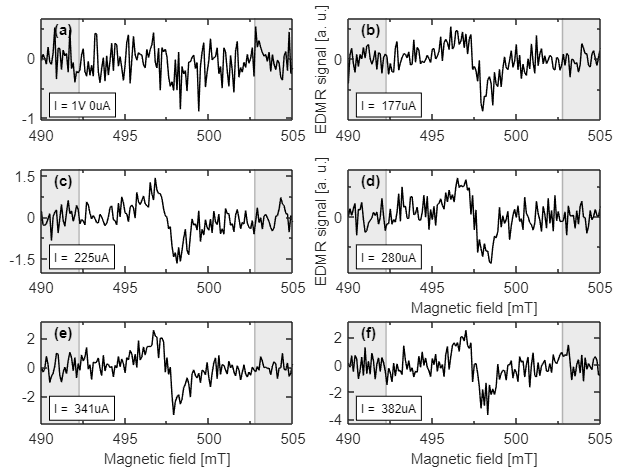

% ID (V and uA): (1.1 148), (1.2 217), (1.25 256), (1.3 294)
figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
LineW = 0.8;
gC = [0.4660 0.6740 0.1880]; % Green color
pC = [0.4940 0.1840 0.5560]; % Purple color

for icw = 1:ncw;
    nexttile
    x_ = cw(icw).x; y_ = cw(icw).y; Width_ = cw(icw).BlOpt.Width;
    plot(x_, y_, 'Color', [0 0 0])
    hold on
    xRectL = min(x_) + Width_*(max(x_) - min(x_));
    rectangle('Position', [0 -50 xRectL 300], ...
        'FaceColor', [0.92 0.92 0.92], 'EdgeColor', [0.7 0.7 0.7]);
    xRectR = max(x_) - Width_*(max(x_) - min(x_));
    rectangle('Position', [xRectR -50 200 300], ...
        'FaceColor', [0.92 0.92 0.92], 'EdgeColor', [0.7 0.7 0.7]);
    
    h = get(gca, 'Children');
    set(gca,'Children',[h(3) h(1) h(2)])
    set(gca, "Layer", "top")
    
    ax = gca;
    ax.Units = 'centimeters';
    ticksLength = 0.025; % cm
    ax.TickLength(1) = ticksLength;
    xTicks = 490:5:505;
    xMinorTicks = 492.5:5:502.5;
    ax.XTick = xTicks;
    ax.XAxis.MinorTick = 'on';
    ax.XAxis.MinorTickValues = xMinorTicks;

    xlim(setAxLim(x_, 0)); ylim(setAxLim(y_, 0.1));

    if icw == 2 || icw == 4
        ylabel('EDMR signal [a. u.]', 'FontSize', 10)
    end
    if icw > 3
        xlabel('Magnetic field [mT]', 'FontSize', 10)
    end

    % title(cw(icw).Title)
    annStr = {sprintf('I = %s', cw(icw).Title(end-5:end))};
    text(0.05, 0.15, annStr, 'Units', 'normalized', ...
        'FontSize', 8, ...
        'BackgroundColor', 'white', ...
        'EdgeColor', 'black');
end
nexttile(1)
ax = gca;
ax.YTick = -1:1:1;
ax.YAxis.MinorTick = 'on';
ax.YAxis.MinorTickValues = [-0.5, 0.5];
nexttile(2)
ax = gca;
ax.YTick = -1.5:1.5:1.5;
ax.YAxis.MinorTick = 'on';
ax.YAxis.MinorTickValues = [-0.75, 0.75];
nexttile(3)
ax = gca;
ax.YTick = -1.5:1.5:1.5;
ax.YAxis.MinorTick = 'on';
ax.YAxis.MinorTickValues = [-0.75, 0.75];
nexttile(4)
ax = gca;
ax.YTick = -2.5:2.5:2.5;
ax.YAxis.MinorTick = 'on';
ax.YAxis.MinorTickValues = [-1.25, 1.25];
annotateSubplotId(tL)

exportStr = input('Export graphics? y/n\n', 's');
if strcmp(exportStr, 'y')
    exportgraphics(gcf, [Opt.SFolder, '/cwEDMR chip.pdf'])
else
    disp('Graphics not exported')
end

Graphics not exported


#### Export

saveStr = input('Export data to .mat file? y/n\n', 's');
if strcmp(saveStr, 'y')
    cwStruct = cw(2:ncw); % Vbias = 1.1 V shows no signal
    [x, y] = deal(zeros(numel(cw(1).x), numel(cwStruct)));
    for icw = 1:numel(cwStruct)
        x(:, icw) = cwStruct(icw).x;
        y(:, icw) = cwStruct(icw).y;
    end
    save([Opt.LFolder, '\cwEDMR_chip'], 'x', 'y', 'cwStruct');
    % exportgraphics(gcf, [Opt.SFolder, '/2022-06-17 cwEDMR forward bias.png'])
else
    disp('Data not exported')
end